# TITLE: Signal Modulation and Detection in an AWGN Channel with LDPC Encoder and Decoder

Authors: Fernando Guiomar [guiomar@av.it.pt](guiomar@av.it.pt) 

Last Update: 09/11/2019

## Initialization

clear;
clear global;
close all;
clc;

% Load Libraries:
addpath(genpath('..\..\..\'));

global PROG;
PROG.showMessagesLevel = 2;
initProg();

Current Date: 10-Nov-2019 01:24:57


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                      PROGRAM INITIALIZATION                      %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Input Parameters

SIG.M = 16;                 % QAM constellation size
SIG.symRate = 60e9;         % total symbol-rate of the signal
SIG.modulation = 'QAM';     % modulation type [QAM/PAM]
SIG.rollOff = 0.1;          % roll-off factor
SIG.nPol = 1;               % number of polarizations
SIG.nSyms = 2^17;           % total number of simulated symbols
nSpS = 2;                   % number of samples per symbol
laserLW = 1e6;              % laser linewidth [Hz]

FEC_rate = 5/6;             % FEC rate

pilotRate = 31/32;          % Pilot rate
useCPE2 = false;            % flag to decide whether to use 2nd CPE or not

SNR_dB = 13;                % SNR in dB

## Set Transmitter Parameters

#### Signal Parameters:

TX.SIG = setSignalParams('symRate',SIG.symRate,'M',SIG.M,...
    'nPol',SIG.nPol,'nBpS',log2(SIG.M),'nSyms',SIG.nSyms,...
    'roll-off',SIG.rollOff,'modulation',SIG.modulation);

#### Modulation Parameters:

TX.QAM = QAM_config(TX.SIG);

#### Bit Parameters:

TX.BIT.source = 'randi';
TX.BIT.seed = 1;

#### Pulse Shaping Filter Parameters:

TX.PS.type = 'RRC';
TX.PS.rollOff = TX.SIG.rollOff;
TX.PS.nTaps = 128;

#### DAC Parameters:

TX.DAC.RESAMP.sampRate = nSpS*TX.SIG.symRate;

#### LASER Parameters:

TX.LASER.linewidth = laserLW;

#### DSP Pilots Parameters:

TX.PILOTS.active = true;
TX.PILOTS.rate = pilotRate;
TX.PILOTS.option = 'outerQPSK';
% TX.PILOTS.scaleFactor = 1;

#### FEC Parameters:

TX.FEC.active = true;
TX.FEC.rate = FEC_rate;
TX.FEC.nIter = 50;

#### Calculate Transmitted Net Bit-Rate:

bitRate_net = SIG.nPol * SIG.symRate * log2(SIG.M) * TX.PILOTS.rate * TX.FEC.rate;
fprintf('Transmitted net bit-rate: %1.4f Gbps\n',bitRate_net*1e-9);

Transmitted net bit-rate: 193.7500 Gbps


## Generate Tx Bits

TX.BIT.txBits = Tx_generateBits(SIG.nSyms,TX.QAM.M,TX.QAM.nPol,TX.BIT);

## Generate Transmitted Symbols

[S.tx,TX.BIT.txSyms] = Tx_QAM(TX.QAM,TX.BIT.txBits);

#### Plot Transmitted Constellation Symbols:

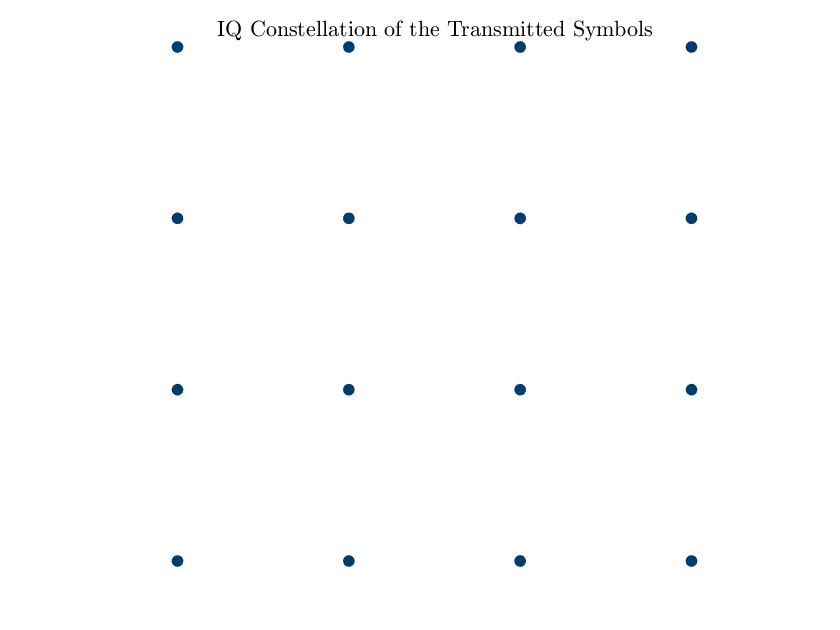

scatterPlot(S.tx,'markersize:sig',20);
title('IQ Constellation of the Transmitted Symbols','interp','latex')

## Add FEC Overhead

if TX.FEC.active
    [S.tx,txSyms,txBits,TX.FEC] = LDPC_encoder_QAM(TX.BIT.txBits,TX.FEC,TX.QAM.IQmap);
    TX.BIT.txBits_afterFEC = txBits;
    TX.BIT.txSyms_afterFEC = txSyms;
end

## Add DSP Pilots

if isfield(TX,'PILOTS') && TX.PILOTS.active && TX.PILOTS.rate < 1
    [S.tx,TX.PILOTS] = Tx_addPilots(S.tx,TX.PILOTS,TX.QAM.IQmap);
    TX.QAM.meanConstPower = mean(abs(S.tx).^2,2);
    TX.QAM.maxConstPower = max(abs(S.tx).^2,[],2);
end

#### Plot Pilot Symbols:

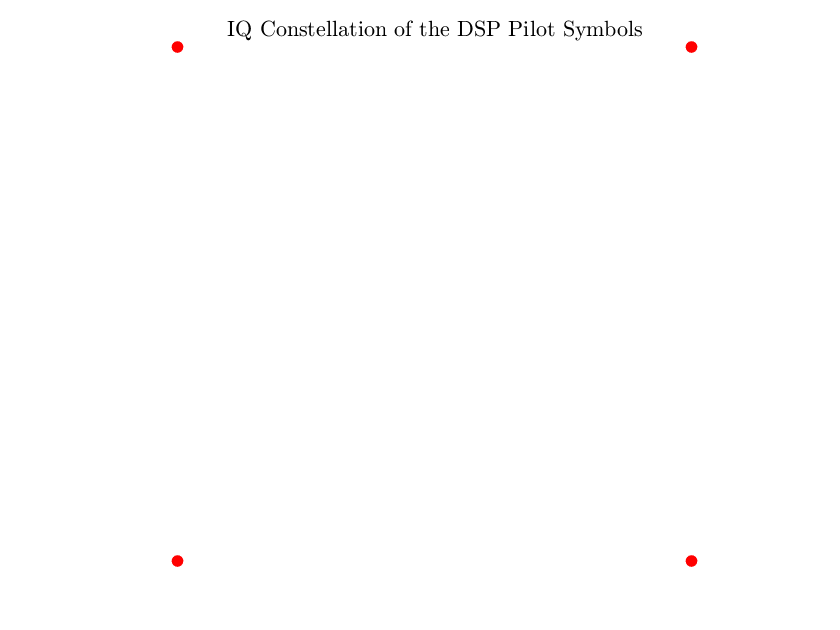

scatterPlot(TX.PILOTS.pilotSequence,'markersize:sig',20,'markercolor:sig','r');
title('IQ Constellation of the DSP Pilot Symbols','interp','latex')

## Pulse Shaping

[S.txSC,TX.PS] = pulseShaper(S.tx,nSpS,TX.PS);

#### Plot Pulse Shaping Taps

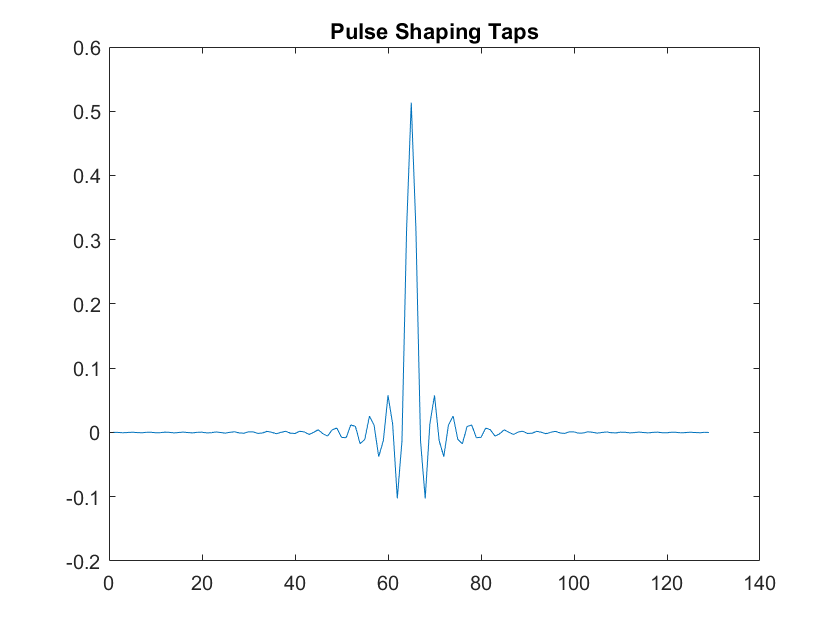

figure();
plot(TX.PS.W);
title('Pulse Shaping Taps')

#### Plot Signal Spectrum

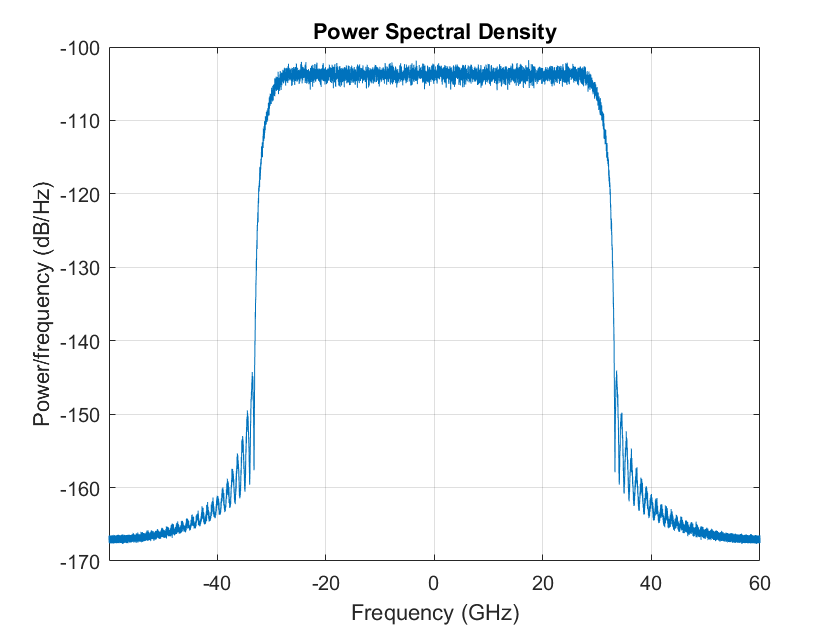

figure();
pwelch(S.txSC(1,:),1e4,[],[],TX.DAC.RESAMP.sampRate,'centered')

## Digital-to-Analog Converter

Fs_SC = nSpS * SIG.symRate;
[S.txSC,TX.DAC] = Tx_DAC(S.txSC,TX.DAC,Fs_SC);

## Apply Laser

nSamples = size(S.tx,2) * nSpS;
[Scw,TX.LASER] = laserCW(TX.LASER,Fs_SC,nSamples);
nPol = size(S.txSC,1);
if nPol == 2
    Scw = Scw/sqrt(2);      % divide CW power by 2 if dual-pol
end
for n = 1:nPol
    S.txSC(n,:) = Scw.*S.txSC(n,:);
end

#### Plot Laser Phase Noise

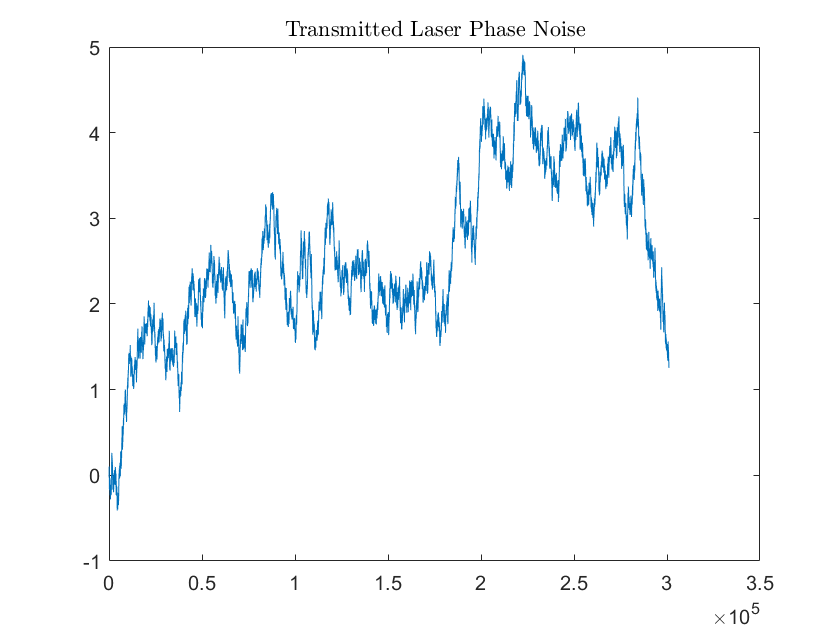

figure();
plot(TX.LASER.phaseNoise)
title('Transmitted Laser Phase Noise','interp','latex')

## Set SNR

S.rx = setSNR(S.txSC,SNR_dB,TX.DAC.RESAMP.sampRate,SIG.symRate);

#### Plot Received Signal Spectrum:

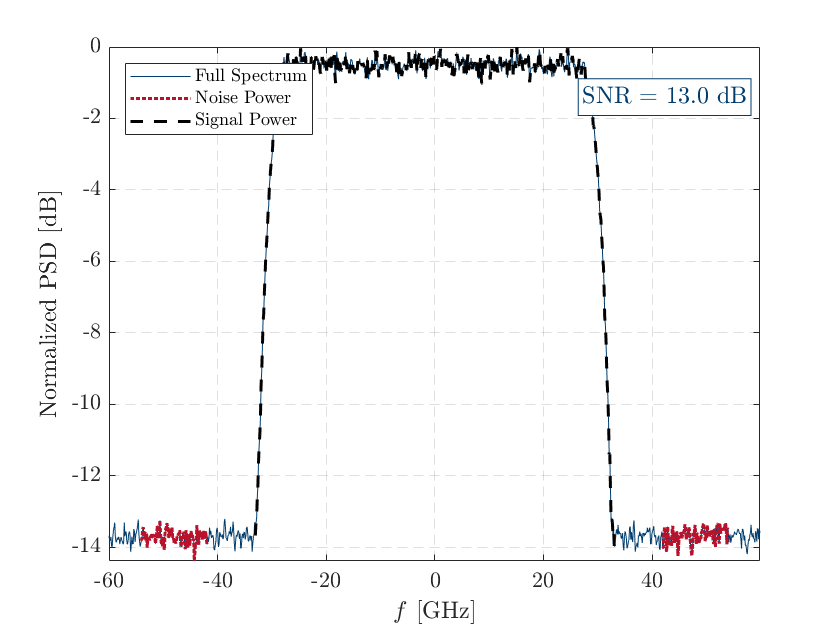

Sf = pwelch(S.rx,1e3,[],[],Fs_SC,'centered','psd').';
[SNR_rx_dB,Ps,Pn] = SNR_estimateFromSpectrum(Sf,Fs_SC,TX.SIG.symRate,...
    TX.SIG.rollOff,[-0.9 -0.7; 0.7 0.9],0,true);

## Set DSP Parameters

%% Matched-Filter:
DSP.MF.type = 'RRC';
DSP.MF.rollOff = TX.SIG.rollOff;

%% Carrier-Phase Estimation - 1st Stage:
DSP.CPE1.method = 'pilot-based:optimized';
DSP.CPE1.decision = 'data-aided';
% DSP.CPE1.nTaps = 15;
DSP.CPE1.nTaps_min = 1;
DSP.CPE1.nTaps_max = 201;
DSP.CPE1.PILOTS = TX.PILOTS;

%% Carrier-Phase Estimation - 1st Stage:
% DSP.CPE2.method = 'BPS:optimized';
DSP.CPE2.method = 'BPS';
DSP.CPE2.nTaps = 22;
DSP.CPE2.nTaps_min = 1;
DSP.CPE2.nTaps_max = 501;
DSP.CPE2.nTestPhases = 10;
DSP.CPE2.angleInterval = pi/8;

%% Demapper:
DSP.DEMAPPER.normMethod = 'MMSE';

## Apply Matched Filter

S.rx = LPF_apply(S.rx,DSP.MF,TX.DAC.RESAMP.sampRate,SIG.symRate);

## Downsample to 1 Sample/Symbol

S.rx_1sps = S.rx(1:nSpS:end);

#### Plot Received Constellation Symbols:

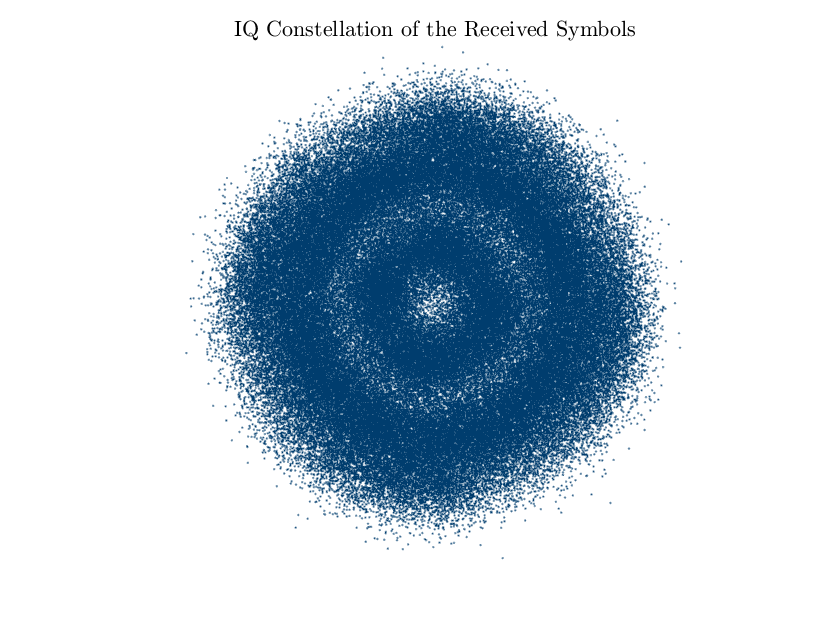

scatterPlot(S.rx_1sps);
title('IQ Constellation of the Received Symbols','interp','latex')

## Apply 1st-Stage CPE: Pilot-Based

[S.rx_1sps,DSP.CPE1] = carrierPhaseEstimation(S.rx_1sps,S.tx,DSP.CPE1);

## Apply 2nd-Stage CPE: Blind-Phase Search

C = TX.QAM.IQmap;
if useCPE2
    [S.rx_1sps,DSP.CPE2] = carrierPhaseEstimation(S.rx_1sps,S.tx,DSP.CPE2,C);
end

## Remove DSP Pilots

[S.rx_1sps,S.tx] = pilotSymbols_rmv(S.rx_1sps,S.tx,DSP.CPE1.PILOTS);

## Apply Symbol Demapper

[DSP.DEMAPPER,S.tx] = symDemapper(S.rx_1sps,S.tx,C,DSP.DEMAPPER);

#### Calculate Bit-Error Ratio (BER):

[BER,errPos] = BER_eval(DSP.DEMAPPER.txBits,DSP.DEMAPPER.rxBits);

#### Calculate Error Vector Magnitude (EVM):

EVM = EVM_eval(S.rx_1sps,S.tx);

#### Calculate Mutual Information (MI) and Generalized Mutual Information (GMI):

MI = MI_eval(S.rx_1sps,S.tx,DSP.DEMAPPER.C,DSP.DEMAPPER.N0);
[GMI,NGMI] = GMI_eval(S.rx_1sps,DSP.DEMAPPER.txBits,DSP.DEMAPPER.C,DSP.DEMAPPER.N0);

#### Plot Constellation after Demapping:

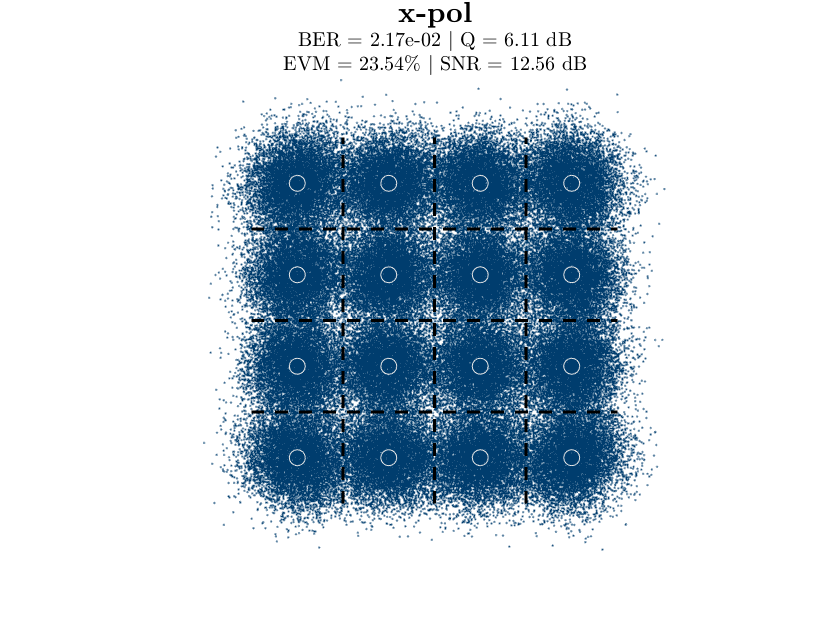

scatterPlot(S.rx_1sps,'BER',BER,'EVM',EVM,'const',DSP.DEMAPPER.C);

## FEC Decoder

DECODER = SC_rxDECODER(DSP.DEMAPPER,TX.BIT,TX.FEC);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                           BIT DECODER                            %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Applying LDPC Decoding... [====================]Done! [4 seconds] 
Bit Decoder - Elapsed Time: 4.4332 [s]


DSP.DEMAPPER = mergeStructs(DSP.DEMAPPER,DECODER);

#### Calculate Bit-Error Ratio (BER):

BER_postFEC = BER_eval(DSP.DEMAPPER.txBits_afterFEC,DSP.DEMAPPER.rxBits_afterFEC);

## AWGN Theory

BERt = snr2ber(SNR_dB,SIG.M);
EVMt = 10^(-SNR_dB/20)*100;
[NGMIt,GMIt,MIt] = snr2gmi(SNR_dB,SIG.M,log2(SIG.M));

## Print Results

entranceMsg('RESULTS');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                             RESULTS                              %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


fprintf('\nBER (theory): %1.3e',BERt);


BER (theory): 1.716e-02

fprintf('\nBER (pre-FEC): %1.3e',BER);


BER (pre-FEC): 2.171e-02

fprintf('\nBER (post-FEC): %1.3e\n',BER_postFEC);


BER (post-FEC): 0.000e+00


fprintf('\nEVM (theory): %1.3f%%',EVMt);


EVM (theory): 22.387%

fprintf('\nEVM: %1.3f%%',EVM);


EVM: 23.538%

fprintf('\n\nMI (theory): %1.3f',MIt);



MI (theory): 3.738

fprintf('\nMI: %1.3f\n',MI);


MI: 3.672


fprintf('\nGMI (theory): %1.3f\n',GMIt);


GMI (theory): 3.738


fprintf('\nGMI: %1.3f\n',GMI);


GMI: 3.672


fprintf('\nNGMI (theory): %1.3f\n',NGMIt);


NGMI (theory): 0.934


fprintf('\nNGMI: %1.3f\n',NGMI);


NGMI: 0.918


## Exit PROG

exitProg();



Total Elapsed Time: 14.8431 [s]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                               END                                %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
